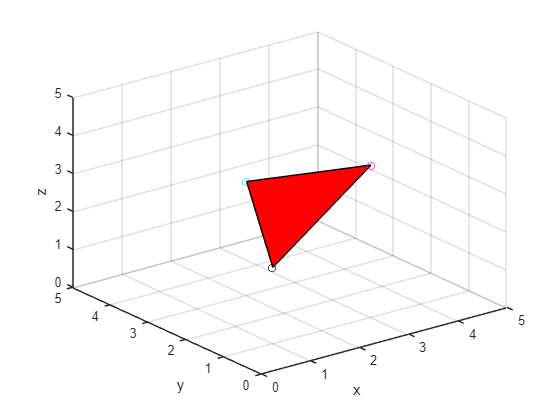

close all, clear all, clc

x = [1,2,3,2];
y = [1,3,1,2];
z = [2,3,4,2.5];
colors = [[0,0,0], %A Black
          [0,1,1], %B Cyan
          [1,0,1], %C Magenta
          [1,1,0]];%D Yellow
labels = ['A','B','C','D'];
scatter3(x,y,z,30,colors)
xlim([0,5])
ylim([0,5])
zlim([0,5])
xlabel('x')
ylabel('y')
zlabel('z')
A = [x(1),y(1),z(1)]; B = [x(2),y(2),z(2)];
C = [x(3),y(3),z(3)]; D = [x(4),y(4),z(4)];
hold on
patch(x(1:3),y(1:3),z(1:3),'r')

% surf(x(1:3),y(1:3),z(1:3))
points = [A;B;C;D]

points =     1.0000    1.0000    2.0000
    2.0000    3.0000    3.0000
    3.0000    1.0000    4.0000
    2.0000    2.0000    2.5000


% idxs1 = [1,3,4,2];
% idxs2 = [2,1,3,1];
% idxs3 = [3,4,2,4];

segment1 = A-B;
segment2 = A-C;
Nvec = cross(segment1,segment2)

Nvec =      4     0    -4


Nvec = Nvec/norm(Nvec)

Nvec =     0.7071         0   -0.7071


k = - (C(1)*Nvec(1)+C(2)*Nvec(2)+C(3)*Nvec(3))

k = 0.7071

eq = [Nvec,k]

eq =     0.7071         0   -0.7071    0.7071


A(1)*eq(1)+A(2)*eq(2)+A(3)*eq(3)+eq(4)

ans = 0

B(1)*eq(1)+B(2)*eq(2)+B(3)*eq(3)+eq(4)

ans = 0

C(1)*eq(1)+C(2)*eq(2)+C(3)*eq(3)+eq(4)

ans = 0

% D(1)*eq(1)+D(2)*eq(2)+D(3)*eq(3)+eq(4)
distance = @(P) abs(eq(1)*P(1)+eq(2)*P(2)+eq(3)*P(3)+eq(4))/sqrt(eq(1)^2+eq(2)^2+eq(3)^2);

distance(A)

ans = 0

distance(B)

ans = 0

distance(C)

ans = 0

distance(D)

ans = 0.3536


angle = @(seg1,seg2) acos((dot(seg1,seg2))/(norm(seg1)*norm(seg2)));
angle(segment1,segment2)

ans = 0.9553

% planes = zeros(4,4);
% for i = 1:4
%     segment1 = points(idxs1(i),:) - points(idxs2(i),:);
%     segment2 = points(idxs1(i),:) - points(idxs3(i),:);
%     cross(segment1,segment2)
% %     theta
% %     iProduct = dot(segment1,segment2);
% %     modA = norm(segment1);
% %     modB = norm(segment2);
% %     thetas(i) = acos(iProduct/(modA*modB));
%     planes(i,:) = zeros(1,4);
% end